clear
p=2;
n=10;
m=100000;
nu=n-1;

mu_h=67;sig_h=2;
mu_w=150;sig_w=4;
rho=0.75;
S=[sig_h*sig_h rho*sig_h*sig_w;
   rho*sig_h*sig_w sig_w*sig_w];
A=chol(S)';

k=n*m;
U1k=rand(k,1);
U2k=rand(k,1);
Z1k=sqrt(-2.*log(U1k)).*cos(2*pi.*U2k);
Z2k=sqrt(-2.*log(U1k)).*sin(2*pi.*U2k);
Xf=[Z1k';Z2k'];

XX=A*Xf+repmat([mu_h;mu_w],[1,n*m]);
X=zeros(p,n,m);
for j=1:m
    X(:,:,j)=XX(:,(j-1)*n+1:n*j);
end

Meanx=squeeze(mean(X,2))

Meanx =    68.0592   66.3410   67.3042   66.8416   66.9271   67.6262   66.9195   67.4164   66.7871   66.7355   67.8432   66.8762   67.2606   67.2680   67.5133   66.5026   67.0689   67.1852   65.4834   65.7502   67.8556   67.0350   65.4366   66.0643   66.9291   66.9130   67.2259   66.6292   66.5785   65.6146   68.0371   67.5550   68.2956   65.7922   67.2600   66.1651   67.2637   65.8652   66.5719   67.9377   67.1512   67.8892   66.0542   66.8862   67.5623   65.7742   66.5845   67.4114   66.4445   66.0287
  151.7064  147.6450  149.2043  150.7268  150.7002  149.0343  149.2644  153.2750  150.6001  148.2375  151.3298  149.6997  150.2850  150.0166  151.6236  149.3822  152.1409  149.7395  148.7873  148.5802  152.0173  149.0786  147.7349  147.6371  149.9274  150.4573  150.1412  149.0721  148.7308  147.4055  150.9080  151.1607  152.3405  147.3929  151.1898  148.2067  150.8099  148.2465  148.2599  152.2140  149.3536  151.4187  148.9827  149.3768  150.4293  147.9785  148.5259  150.6487  149.9455 

covX=zeros(p,p,m);

for j = 1:m
    covX(:,:,j)=cov(squeeze(X(:,:,j)'));
end

Gi=(n-1)*covX;
for j=1:m
    Gi(:,:,j)=inv(Gi(:,:,j));
end
Gi

Gi = Gi(:,:,1) =

    0.0393   -0.0083
   -0.0083    0.0074


Gi(:,:,2) =

    0.0322   -0.0179
   -0.0179    0.0225


Gi(:,:,3) =

    0.0689   -0.0278
   -0.0278    0.0151


Gi(:,:,4) =

    0.0248   -0.0144
   -0.0144    0.0240


Gi(:,:,5) =

    0.0849   -0.0362
   -0.0362    0.0268


Gi(:,:,6) =

    0.0524   -0.0130
   -0.0130    0.0081


Gi(:,:,7) =

    0.0826   -0.0352
   -0.0352    0.0271


Gi(:,:,8) =

    0.1293   -0.0512
   -0.0512    0.0270


Gi(:,:,9) =

    0.0754   -0.0375
   -0.0375    0.0240


Gi(:,:,10) =

    0.0528   -0.0127
   -0.0127    0.0118


Gi(:,:,11) =

    0.0323   -0.0111
   -0.0111    0.0090


Gi(:,:,12) =

    0.0419   -0.0181
   -0.0181    0.0181


Gi(:,:,13) =

    0.0964   -0.0375
   -0.0375    0.0173


Gi(:,:,14) =

    0.0578   -0.0228
   -0.0228    0.0136


Gi(:,:,15) =

    0.0574   -0.0228
   -0.0228    0.0190


Gi(:,:,16) =

    0.0851   -0.0381
   -0.0381    0.0211


Gi(:,:,17) =

    0.1807   -0.0789
   -0.0789    0.0397


Gi(:,:,18) =

    

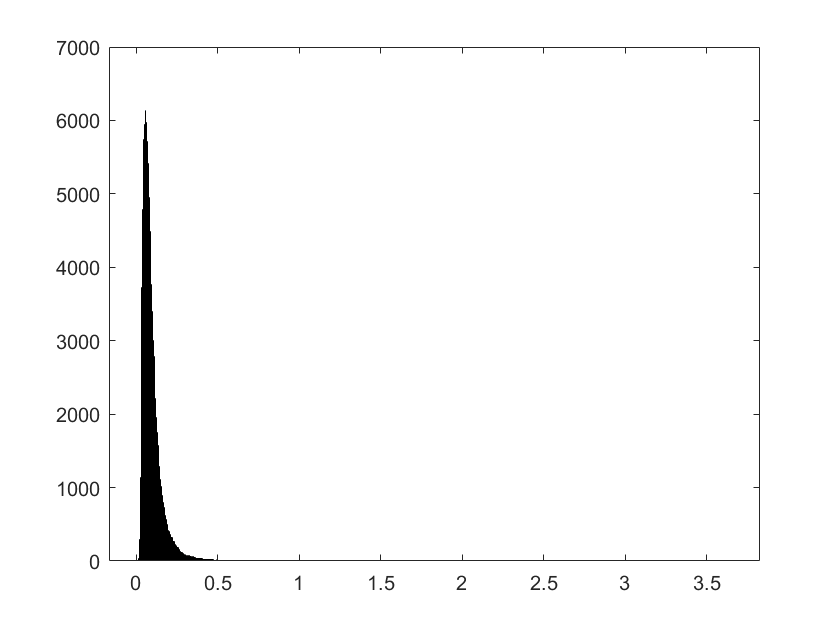


histogram(Gi(1,1,:))

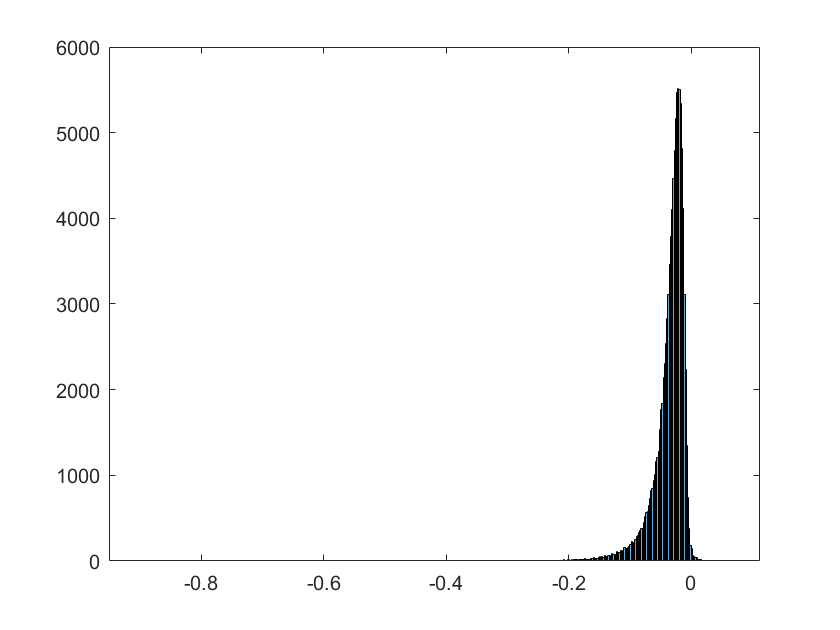

histogram(Gi(1,2,:))

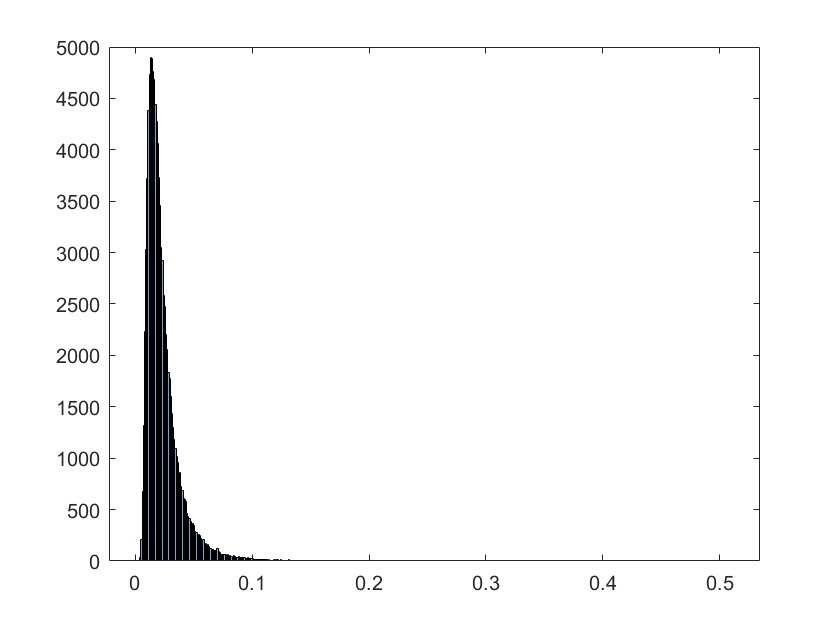

histogram(Gi(2,2,:))


%mean
Q=inv(S);
Mean_Gi=[mean(reshape(Gi(1,1,:),m,1)) mean(reshape(Gi(1,2,:),m,1));
    mean(reshape(Gi(2,1,:),m,1)) mean(reshape(Gi(2,2,:),m,1))]

Mean_Gi =     0.0949   -0.0355
   -0.0355    0.0237



Th_Mean=Q/(nu-p-1)

Th_Mean =     0.0952   -0.0357
   -0.0357    0.0238



%var
Var_Gi=var(Gi,[],3)

Var_Gi =     0.0043    0.0008
    0.0008    0.0003


V11=2*Q(1,1)*Q(1,1)/((nu-p-1)*(nu-p-1)*(nu-p-3));
V22=2*Q(2,2)*Q(2,2)/((nu-p-1)*(nu-p-1)*(nu-p-3));
V12=((nu-p+1)*Q(1,2)*Q(1,2)+(nu-p-1)*Q(1,1)*Q(2,2))/((nu-p)*(nu-p-1)*(nu-p-1)*(nu-p-3));
V21=((nu-p+1)*Q(2,1)*Q(2,1)+(nu-p-1)*Q(2,2)*Q(1,1))/((nu-p)*(nu-p-1)*(nu-p-1)*(nu-p-3));
Th_var=[V11 V12;
        V21 V22]

Th_var =     0.0045    0.0009
    0.0009    0.0003



%cov
covH1112=cov(squeeze(Gi(1,1,:)),squeeze(Gi(1,2,:)));
covH1122=cov(squeeze(Gi(1,1,:)),squeeze(Gi(2,2,:)));
covH1222=cov(squeeze(Gi(1,2,:)),squeeze(Gi(2,2,:)));
Cov_Gi=[covH1112(1,2),covH1122(1,2),covH1222(1,2)]

Cov_Gi =    -0.0016    0.0006   -0.0004



i=1;j=1;k=1;l=2;
cH1112=(2*Q(i,j)*Q(k,l)+(nu-p-1)*(Q(i,k)*Q(j,l)+Q(i,l)*Q(k,j)))/((nu-p)*(nu-p-1)^2*(nu-p-3));
i=1;j=1;k=2;l=2;
cH1122=(2*Q(i,j)*Q(k,l)+(nu-p-1)*(Q(i,k)*Q(j,l)+Q(i,l)*Q(k,j)))/((nu-p)*(nu-p-1)^2*(nu-p-3));
i=1;j=2;k=2;l=2;
cH1222=(2*Q(i,j)*Q(k,l)+(nu-p-1)*(Q(i,k)*Q(j,l)+Q(i,l)*Q(k,j)))/((nu-p)*(nu-p-1)^2*(nu-p-3));
Th_cov=[cH1112,cH1122,cH1222]

Th_cov =    -0.0017    0.0007   -0.0004
